# Runge's Phenomenon

## Setup

f = @(x) 1 / (1 + x.^2);
E = zeros(12,1);


## Linear grid

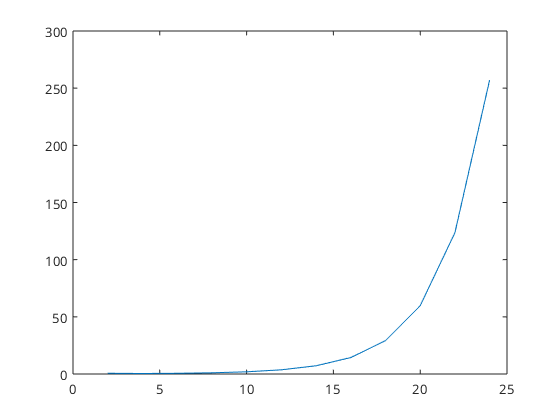

for i = 1:12
    X = -5:(10/(2*i)):5;
    test = test_lagrange_interpolation(f, X, .01);
    E(i) = norm(test,"inf");
end

plot(2:2:24,E);

## Using Chebyshev nodes

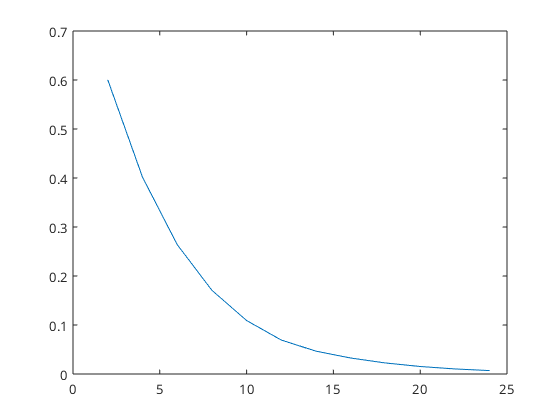

for i = 1:12
    n = 2*i+1;
    X = 5.*cos( (2*(0:n-1)+1) / (2*n) * pi );
    test = test_lagrange_interpolation(f, X, .01);
    E(i) = norm(test,"inf");
end

plot(2:2:24,E);